# Signal Processing II (Fourier Transform)

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2020-12-12

### Sinc Function

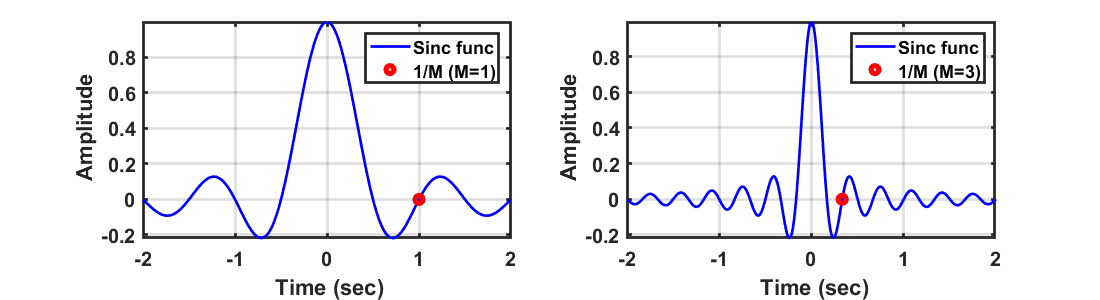

clear; close all; clc;

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 300]);

t = -2:0.01:2 + realmin;
M = 1;
y = sin(2*pi*t*M)./(2*pi*M*t);
subplot(121); plot(t,y,'-b', 'linewidth', 2);
hold on; plot(1/M,0,'or', 'linewidth', 4); hold off;
legend('Sinc func', '1/M (M=1)')
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');


t = -2:0.01:2 + realmin;
M = 3;
y = sin(2*pi*t*M)./(2*pi*M*t);
subplot(122); plot(t,y,'-b', 'linewidth', 2);
hold on; plot(1/M,0,'or', 'linewidth', 4); hold off;
legend('Sinc func', '1/M (M=3)')
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Fourier Transform Pairs (**Exponentially Decaying Symmetric Function)**

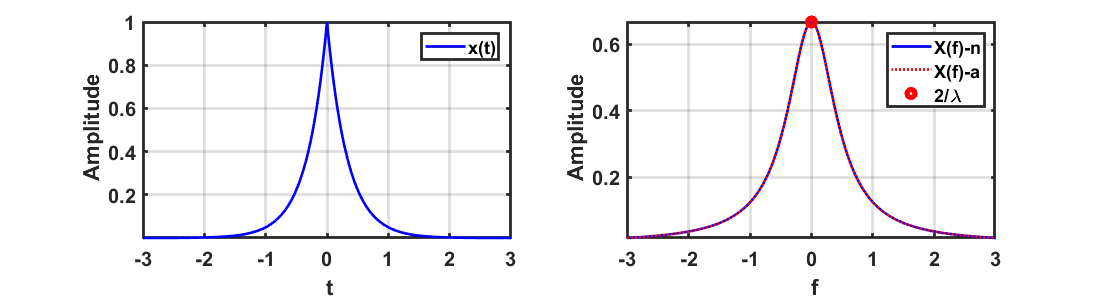

clear; close all; clc;

lambda = 3;
x = @(t) exp(-lambda.*abs(t));
x_in = @(t, f) x(t)*exp(-sqrt(-1)*2*pi*f*t);
Xf = @(f) integral(@(t) x_in(t, f), -inf, inf,'ArrayValued',true);
Xf_analytic = @(f) 2*lambda./(lambda^2 + 4*pi*pi.*f.*f);
t = -3:0.01:3;
f = -3:0.01:3;

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 300]);

subplot(121);plot(t,x(t),'-b', 'linewidth', 2);
legend('x(t)');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf t');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(122);plot(f,abs(Xf(f)),'-b', 'linewidth', 2);
hold on; plot(f,Xf_analytic(f),':r', 'linewidth', 2);
plot(0, 2/lambda,'or', 'linewidth', 4); hold off;
legend('X(f)-n','X(f)-a', '2/\lambda');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf f');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### **Exponentially Decaying Symmetric Function with Different Lambda Values**

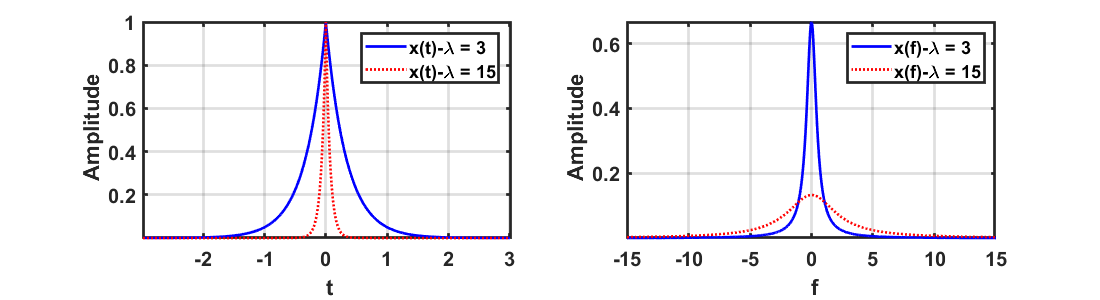

clear; close all; clc;

lambda = 3;
x1 = @(t) exp(-lambda.*abs(t));
Xf_analytic1 = @(f) 2*lambda./(lambda^2 + 4*pi*pi.*f.*f);

lambda = 15;
x2 = @(t) exp(-lambda.*abs(t));
Xf_analytic2 = @(f) 2*lambda./(lambda^2 + 4*pi*pi.*f.*f);

t = -3:0.01:3;
f = -15:0.01:15;

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 300]);

subplot(121);plot(t,x1(t),'-b',t,x2(t),':r', 'linewidth', 2);
legend('x(t)-\lambda = 3','x(t)-\lambda = 15');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf t');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(122);plot(f,Xf_analytic1(f),'-b', 'linewidth', 2);
hold on; plot(f,Xf_analytic2(f),':r', 'linewidth', 2);
legend('x(f)-\lambda = 3','x(f)-\lambda = 15');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf f');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Rectangular Function with Different Ranges

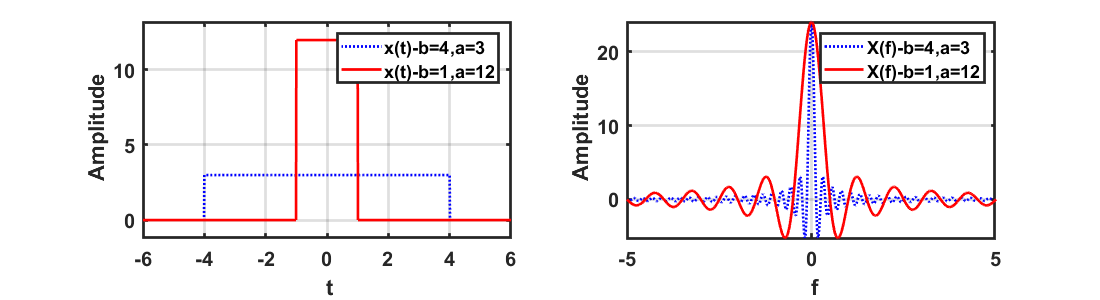

clear; close all; clc;

a = 3;
b = 4;
x1 = @(t) a*(abs(t)<=b) + 0;
Xf_analytic1 = @(f) 2*a*b*sin(2*pi*f*b)./(2*pi*f*b);

a = 12;
b = 1;
x2 = @(t) a*(abs(t)<=b) + 0;
Xf_analytic2 = @(f) 2*a*b*sin(2*pi*f*b)./(2*pi*f*b);

t = -6:0.01:6;
f = [-5:0.01:5] +realmin;

fig5 = figure(5);
set(fig5,'Position', [100 100 1100 300]);

subplot(121);plot(t,x1(t),':b',t, x2(t), '-r', 'linewidth', 2);
legend('x(t)-b=4,a=3', 'x(t)-b=1,a=12');
axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-a*0.1 a*1.1]);
xlabel('\bf t');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(122);plot(f,Xf_analytic1(f),':b', 'linewidth', 2); hold on;
plot(f,Xf_analytic2(f),'-r', 'linewidth', 2);
legend('X(f)-b=4,a=3','X(f)-b=1,a=12');hold off;
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf f');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Fourier Transform Pairs (**Damped Symmetrically Oscillating Function)**

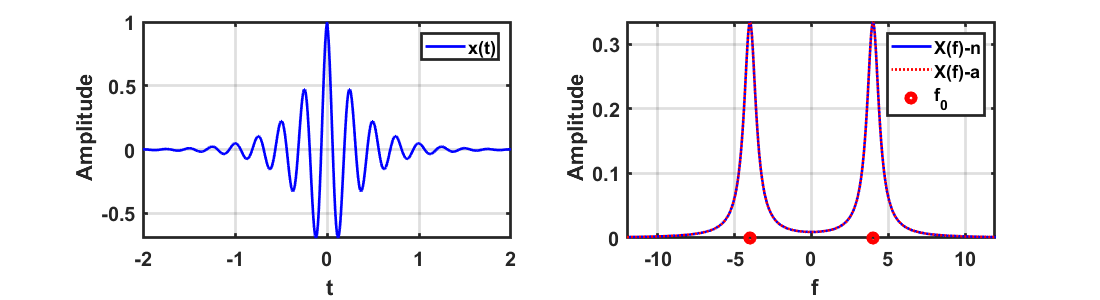

clear; close all; clc;

a = 3;
f_0 = 4;

x = @(t) exp(-a.*abs(t)).*cos(2*pi*f_0*t);
x_in = @(t, f) x(t)*exp(-sqrt(-1)*2*pi*f*t);
Xf = @(f) integral(@(t) x_in(t, f), -inf, inf,'ArrayValued',true);

Xf_analytic = @(f) a./(a^2+(2*pi*(f-f_0)).^2) + a./(a^2+(2*pi*(f+f_0)).^2);

t = -2:0.01:2;
f = [-12:0.01:12] +realmin;

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 300]);

subplot(121);plot(t,x(t),'-b', 'linewidth', 2);
legend('x(t)');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf t');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(122);plot(f,abs(Xf(f)),'-b', 'linewidth', 2);
hold on; plot(f,Xf_analytic(f),':r', 'linewidth', 2);
plot([-f_0 f_0], [0 0],'or', 'linewidth', 4); hold off;
legend('X(f)-n','X(f)-a', 'f_0');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf f');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Fourier Transform Pairs (Gaussian** Function)**

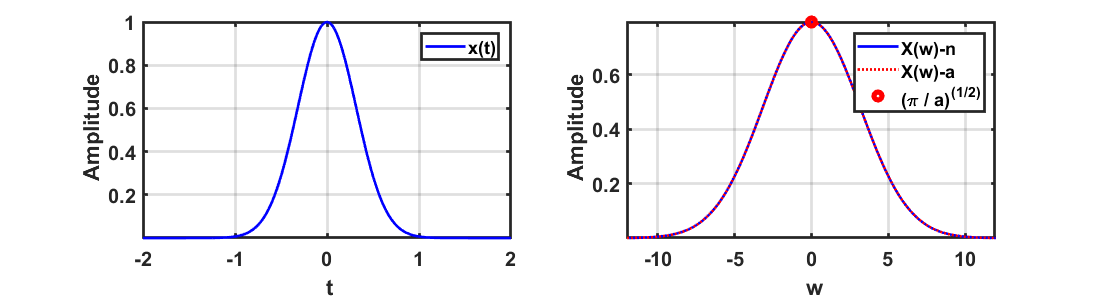

clear; close all; clc;

a = 5;

x = @(t) exp(-a.*t.*t);
x_in = @(t, w) x(t)*exp(-sqrt(-1)*w*t);
Xw = @(w) integral(@(t) x_in(t, w), -inf, inf,'ArrayValued',true);
Xw_analytic = @(w) sqrt(pi/a).*exp(-w.*w/(4*a));

t = -2:0.01:2;
w = [-12:0.01:12] +realmin;

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 300]);

subplot(121);plot(t,x(t),'-b', 'linewidth', 2);
legend('x(t)');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf t');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(122);plot(w,real(Xw(w)),'-b', 'linewidth', 2);
hold on; plot(w,Xw_analytic(w),':r', 'linewidth', 2);
plot(0, sqrt(pi/a),'or', 'linewidth', 4); hold off;
legend('X(w)-n','X(w)-a', '(\pi / a)^{(1/2)}');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf w');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Gaussian Function with Different Variances

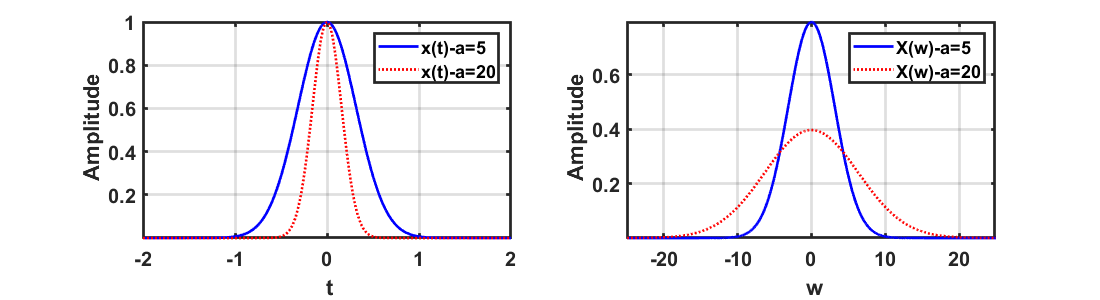

clear; close all; clc;

a = 5;
x1 = @(t) exp(-a.*t.*t);
Xw_analytic1 = @(w) sqrt(pi/a).*exp(-w.*w/(4*a));

a = 20;
x2 = @(t) exp(-a.*t.*t);
Xw_analytic2 = @(w) sqrt(pi/a).*exp(-w.*w/(4*a));

t = -2:0.01:2;
w = [-25:0.01:25] +realmin;

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 300]);

subplot(121);plot(t,x1(t),'-b',t, x2(t),':r', 'linewidth', 2);
legend('x(t)-a=5', 'x(t)-a=20');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf t');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(122);plot(w,Xw_analytic1(w),'-b', 'linewidth', 2);
hold on; plot(w,Xw_analytic2(w),':r', 'linewidth', 2); hold off;
legend('X(w)-a=5','X(w)-a=20');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf w');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');